clear
% rng(2025);

# Import Map Data

% Define custom basemap
% name = 'openstreetmap';
% url = 'https://a.tile.openstreetmap.org/${z}/${x}/${y}.png';
% copyright = char(uint8(1)); % Copyright symbol
% attribution = copyright + "OpenStreetMap contributors";
% addCustomBasemap(name, url, 'Attribution', attribution);

% Load JSON file
jsonFile = 'map data\route3.json';
jsonData = jsondecode(fileread(jsonFile));

# Road Settings

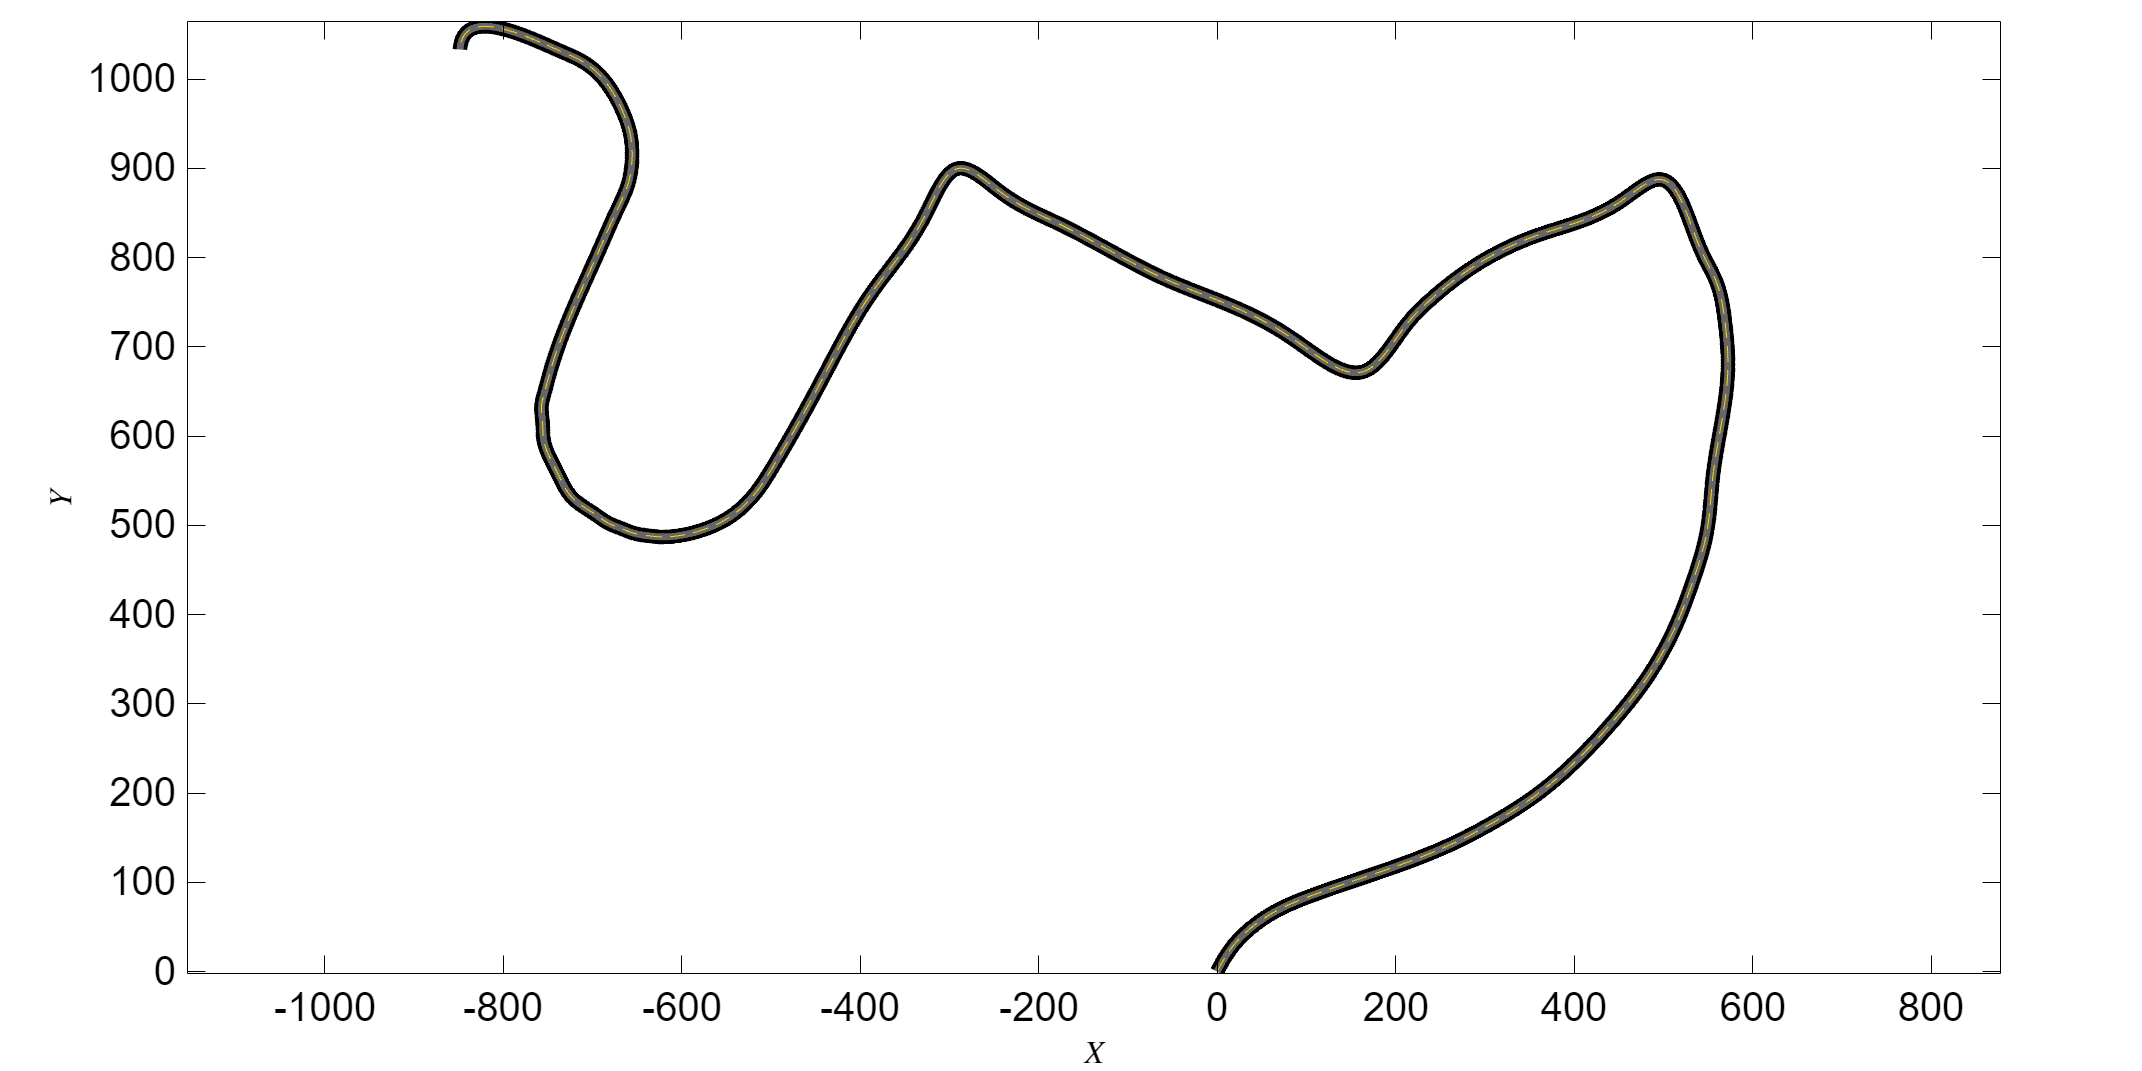

% Trajectory Generation
numberOfLines = 2; % scaler number
lineWidth = 6; % meters
functionBasedFlag = 0; % for 'map' road type it must be set to 0;
roadType = 'map';
dx = 0.5; % road xlength segmentation resolution (in meters)
roadClass = roadMaker(roadType, numberOfLines, lineWidth, functionBasedFlag, dx, 'no', jsonData); % plot flag 'yes' or 'no'

roadClass.plotRoad();


% Precompute interpolants
interpolantSetup = roadClass.precomputeInterpolants();
% roadClass.checkCurvature();

zoomLevel = 15;
stepSize = 100;
pauseTime = 0;
roadClass.animateRoute(zoomLevel, stepSize, pauseTime);